# Enkel Free-Space loss modell

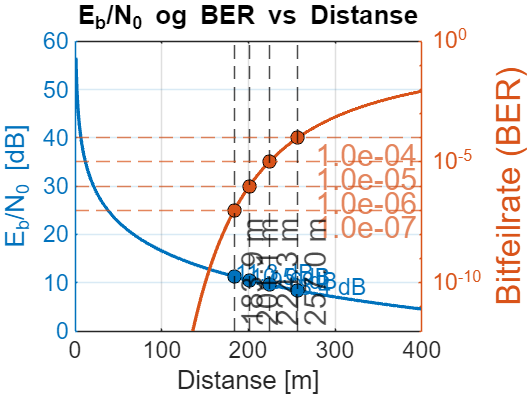

clc; clear; close all;

% Konstanter
c = 3e8;             % Lysfart (m/s)
f = 0.8e9;           % Frekvens (Hz)
lambda = c / f;      % Bølgelengde (m)

% Gitte parametere
EIRP = -20.5;        % dBW
L0 = 12;             % Systemtap (dB)
N0 = -144;           % Støytetthet (dBW/Hz)
Gr = 2.0;            % Mottakerantennens vinning (dBi)
Rb = 26.4;           % Bitrate (dBHz)

% Definer avstand (LINEÆR skala)
d = linspace(1, 400, 1000); % Fra 1 m til 200 m

% Friromstap (Path loss)
L_s = 20*log10(4 * pi * d / lambda); % dB

% Linkbudsjett beregning
Eb_N0_dB = EIRP - L_s - L0 + Gr - Rb - N0; % dB

% Konverter Eb/N0 til lineær verdi
Eb_N0_linear = 10.^(Eb_N0_dB / 10);

% BER for OQPSK/QPSK
BER = qfunc(sqrt(2 * Eb_N0_linear));

% Definer flere BER-grenser
BER_thresholds = [1e-7,1e-6, 1e-5, 1e-4]; 

% --- PLOT ---
figure;

% Bit Energy to Noise Ratio (Eb/N0) Plot (venstre y-akse)
yyaxis left
plot(d, Eb_N0_dB, 'LineWidth', 2); % Plotter Eb/N0 på venstre akse
ylabel('E_b/N_0 [dB]', 'FontSize', 20);
xlabel('Distanse [m]', 'FontSize', 20);
grid on;
title('E_b/N_0 og BER vs Distanse', 'FontSize', 20);
set(gca, 'FontSize', 14);  % Øker skriftstørrelse for akselabels
hold on;

% BER Plot (høyre y-akse)
yyaxis right
semilogy(d, BER, 'LineWidth', 2);  % Gjør y-aksen logaritmisk for BER
ylabel('Bitfeilrate (BER)', 'FontSize', 20);
set(gca, 'YScale', 'log');  % Setter logaritmisk skala for høyre akse
ylim([1e-12, 1]); % Justert BER y-akse

% Iterer over flere BER-grenser og plotter maksimal avstand
for i = 1:length(BER_thresholds)
    % Finn nærmeste distanse hvor BER <= BER_threshold
    idx = find(BER >= BER_thresholds(i), 1, 'first');
    max_distance = d(idx);
    
    % Hent E_b/N_0-verdien ved denne distansen
    Eb_N0_at_maxDist = Eb_N0_dB(idx);
    yyaxis right
    % Plotter maksimal distanse for hver BER-grense
    plot(max_distance, BER(idx), 'ko', 'MarkerFaceColor', [0.850, 0.325, 0.098], 'MarkerSize', 8);
    
    % Legger til en stiplet linje på den aktuelle BER-grensen
    yline(BER_thresholds(i), '--', sprintf('%.1e', BER_thresholds(i)), 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'right','Color',[0.850, 0.325, 0.098],'FontSize',18);
    xline(max_distance, '--k', sprintf('%.1f m', max_distance), 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'right','FontSize',18);

    yyaxis left
    plot(max_distance, Eb_N0_at_maxDist, 'ko', 'MarkerFaceColor', [0, 0.447, 0.741], 'MarkerSize', 8);
    text(max_distance+1, Eb_N0_at_maxDist+0.7, sprintf('%.1f dB', Eb_N0_at_maxDist), 'FontSize', 14, 'Color', [0, 0.447, 0.741]);
end

hold off;

# Shadowing, Log-normal LSF og Rayleigh SSF

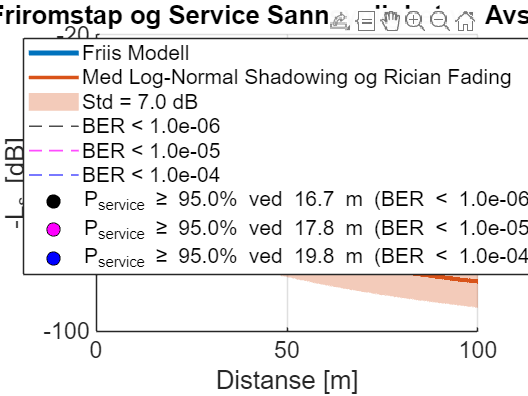

clc; clear; close all;

% Konstanter
c = 3e8;             % Lysfart (m/s)
f = 0.8e9;           % Frekvens (Hz)
lambda = c / f;      % Bølgelengde (m)

% Gitte parametere
EIRP = -20.5;                   % dBW (Sendereffekt)
L0 = 12;                        % Systemtap (dB)
N0 = -144;                      % Støytetthet (dBW/Hz)
Gr = 2.0;                       % Mottakerantennens vinning (dBi)
Rb = 26.4;                      % Bitrate (dBHz)
Eb_N0 = [10.5; 9.6; 8.4];        % BER-thresholds

% Beregn maksimal tillatt path loss (LM) for hver BER-threshold
LM = EIRP - L0 - N0 + Gr - Rb - Eb_N0;  % LM er en (3x1)-vektor

% Path Loss Model Parametere
d0 = 1;                   % Referanseavstand (m)
n = 2.75;                  % Path loss exponent
sigma = 6;                % Shadowing standardavvik (dB)
num_realizations = 1e4;   % Antall realisasjoner

% Definer avstand (LINEÆR skala)
d = linspace(1, 100, 10000);   % Fra 1 m til 100 m

% Friromstap enkel modell
PL = 20*log10(4*pi*d/lambda);

% Friromstap ved referanseavstand d0
PL_d0 = 20*log10(4*pi*d0/lambda);

% Log-normal shadowing path loss (inkluderer referanseverdi)
PL_shadowing = PL_d0 + 10*n*log10(d/d0);

% Generer stokastisk shadowing for flere realisasjoner (Large Scale Fading)
X_sigma = sigma * randn(num_realizations, length(d)); 

% --- Rician fading istedenfor Rayleigh ---
K_dB = 5;  % Rician K-faktor i dB
K = 10^(K_dB/10);  % Konverter til lineær skala

s = sqrt(K / (K + 1));      % LOS-komponent
sigma_rician = sqrt(1 / (2*(K + 1)));  % Ikke-LOS-komponent

% Generer Rician fading
h_rician = (s + sigma_rician * randn(num_realizations, length(d))) + ...
           1i * (sigma_rician * randn(num_realizations, length(d)));

rician_fading = -20 * log10(abs(h_rician));

% Totalt path loss = Shadowing + Rician fading
PL_total = PL_shadowing + X_sigma + rician_fading;
PL_mean = mean(PL_total, 1);
PL_std  = std(PL_total, 1);

% --- Beregn sannsynlighet for mottatt signal P[L_s < LM] ---
P_service = normcdf( repmat(LM, 1, length(d)), ... 
                     repmat(PL_mean, length(LM), 1), ... 
                     repmat(PL_std, length(LM), 1) );

% --- Finne avstand der P_service >= P_target (service probability >= 0.95) ---
P_target = 0.95;
dist_at_P90 = zeros(size(LM));

for i = 1:length(LM)
    idx = find(P_service(i,:) >= P_target, 1, 'last');
    if ~isempty(idx)
        dist_at_P90(i) = d(idx);
    else
        dist_at_P90(i) = NaN;
    end
end

% --- PLOT ---
figure;
hold on;
grid on;

% Plot Friis-modell
plot(d, -PL, 'LineWidth', 3, 'DisplayName', 'Friis Modell');

% Plot middelverdien (med fading)
plot(d, -PL_mean, 'LineWidth', 2, 'DisplayName', 'Med Log-Normal Shadowing og Rician Fading');

% Skygge rundt middelverdien (± standardavvik)
fill([d, fliplr(d)], -[PL_mean+PL_std, fliplr(PL_mean-PL_std)], ...
     [0.850, 0.325, 0.098], 'FaceAlpha', 0.3, 'EdgeColor', 'none', ...
     'DisplayName', sprintf('Std = %.1f dB', mean(PL_std)));

% Plot LM-grenser for de ulike BER-nivåene
BER = [1e-6, 1e-5, 1e-4];
colors = {'black', 'magenta', 'blue'};
for i = 1:length(LM)
    yline(-LM(i),'Linestyle','--', 'Color', colors{i}, 'LineWidth', 1, ...
        'DisplayName', sprintf('BER < %.1e', BER(i)));
end

% Illustrer de avstandene der P_service >= P_target:
for i = 1:length(LM)
    if ~isnan(dist_at_P90(i))
        x_val = dist_at_P90(i);
        y_val = -interp1(d, PL_mean, x_val);
        plot(x_val, y_val, 'ko', 'MarkerFaceColor', colors{i}, 'MarkerSize', 8, ...
            'DisplayName', sprintf('P_{service} ≥ %.1f%% ved %.1f m (BER < %.1e)', P_target*100, x_val, BER(i)));
    end
end

% Aksetilpasning
xlabel('Distanse [m]', 'FontSize', 20);
ylabel('-L_s [dB]', 'FontSize', 20);
xlim([0,100]);
title('Friromstap og Service Sannsynlighet vs Avstand', 'FontSize', 20);
set(gca, 'FontSize', 14);
legend('Location','best','AutoUpdate','on');
hold off;